# Fourier Analysis

*Bart Krekelberg - Last Update Jan 2023.*

Fourier analysis (also called spectral analysis) is a powerful method to determine whether data contain periodic (i.e. repeating) components. It is used to analyze data from a wide range of approaches; fMRI, single cell recordings, as well as EEG.

Matlab has a range of functions to perform spectral analysis, the basic ones (such as the basic (fast) Fourier transform) are built-in, while more advanced methods (spectrograms, coherence, or multitaper estimates) are part of the Signal Processing Toolbox. The latter has a very extensive help documentation and several demos that are worth viewing.

## Example Data Sets

First, let's just look at a few data sets where a Fourier analysis would be helpful. 

**Example 1: BOLD Data**

The first set of data is from an fMRI experiment in which a subject viewed images of faces for 16 seconds, followed by images of houses for 16 seconds. These blocks were repeated several times, and we are showing the BOLD signal in one voxel in the fusiform face area:

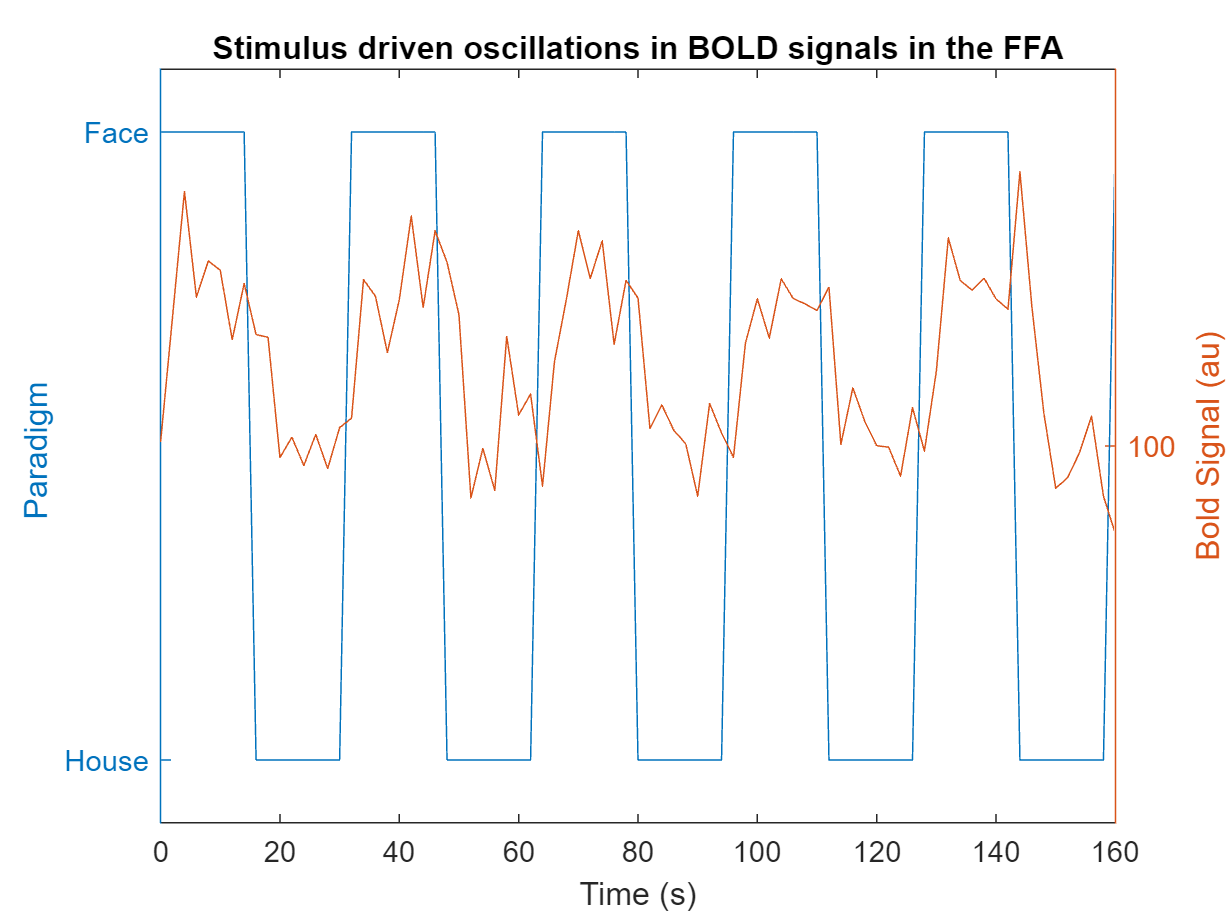

load ../data/boldData
figure(1);
clf;
yyaxis left
plot(boldTime,paradigm);
xlabel 'Time (s)'
ylabel('Paradigm ');
set(gca,'YLim',[-0.1 1.1],'YTick',[0 1],'YTickLabel',{'House','Face'})
yyaxis right
plot(boldTime,bold);
ylabel('Bold Signal (au)');
set(gca,'YLim',[99 101],'YTick',100)
title 'Stimulus driven oscillations in BOLD signals in the FFA'

The BOLD response is clearly periodic. This is likely a reflection of the periodic experimental design (alternations of Face/House/Face/House), so any voxel that is responsive to one but not the other condition should show a periodic response. The goal of spectral analysis is to determine whether there is indeed a periodic response that follows the stimulus paradigm. If there is a periodic response in a voxel, then that supports the idea that the voxel responds more in blocks of one category (e.g. faces) than the other (houses). Please note that Fourier analysis can quantify this periodic response, but in itself it does not provide a statistical estimate of significance; we'll look at this in a later module.

**Example 2: V1 Single Neuron Responses**

Here is a very different kind of recording, the spike density of a single V1 neuron

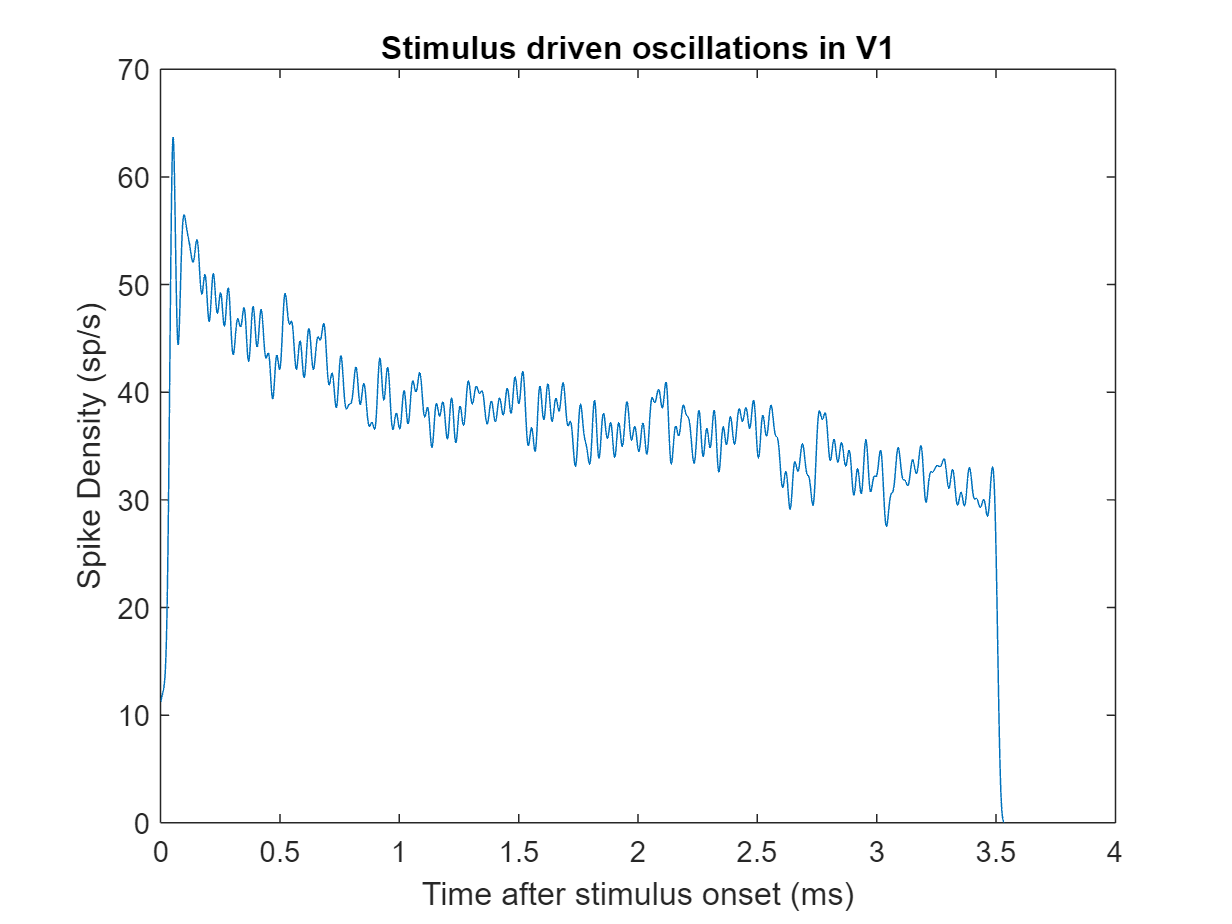

load ../data/v1Data;
clf
plot(v1Time,v1Response);
xlabel 'Time after stimulus onset (ms)'
ylabel 'Spike Density (sp/s)'
title 'Stimulus driven oscillations in V1'

You can see periodic wiggles in the response, but at a much faster time scale. The experimental paradigm in this case involved the rapid presentation of sequences of oriented bars. A new orientation was shown every 33 ms. In other words the input was periodic on a 33 ms time scale. Spectral analysis helps us to determine whether the neural activity is periodic on that same time scale. If it is, then that supports the hypothesis that this neuron responds to visual stimuli.

In both of these  examples, the periodicity in the signal was created by the experimental design. (E.g. we hypothesized that there might be some area that responds to faces, but not houses, therefore we present a periodic sequence of faces/houses/faces/houses and then looked in the BOLD signal to see if there are any voxels that follow this sequence).

The brain, however, also generates perioidc patterns of activity in the absence of periodic input. These have been studied extensively in EEG. For instance, alpha waves (periodic patterns on a ~100 ms time scale) dominate occipital cortex in darkness, and the presence of gamma waves (~25 ms time scale) has been linked to focused attention.

**Example 3: EEG Recordings**

In these EEG data the subject was just sitting, doing "nothing":

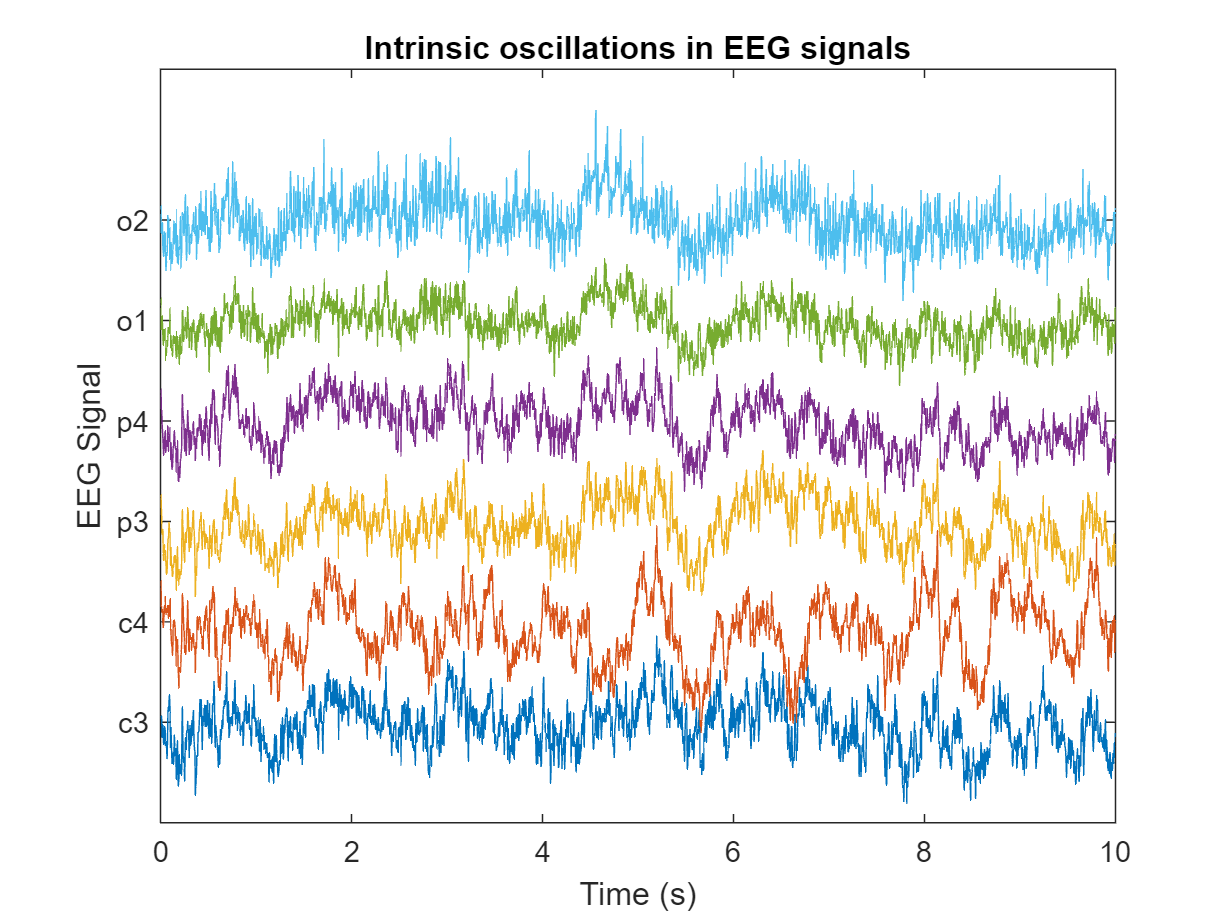

load ../data/eegData;
clf;
nrChannels = size(eegData,2);
offset  =20*(1:nrChannels);
for channel =1:nrChannels
    plot(eegTime,eegData(:,channel)+offset(channel));
    hold on
end
xlabel 'Time (s)'
ylabel 'EEG Signal'
set(gca,'YTick',offset,'YtickLabel',eegChannels)
title 'Intrinsic oscillations in EEG signals'

It certainly looks as if there are periodic changes across all of the channels, although the periodicity may be different (and more pronounced) in c4 compared to o2 and o1 for instance. Spectral analyis is an essential step to quantify and understand these signals. For instance, the presence of specific spectral components (i.e. periodic patterns at a certain frequency) has been linked to high level concepts such as attention, vigilance, and it is used to "score" EEG recorded during sleep (e.g. when did a subject transition from awake (not much periodicity) to sleep (lots of periodic patterns) ? Or from REM (high frequencies) to slow-wave sleep (very low frequencies)?.

## Understanding Fourier Analysis

Matlab has many built-in tools that you can use to do Fourier/Spectral analysis, but before we get into those, let's first get a better understanding of the underlying principles.

The prototypical periodic funciton is the sine wave, it has an amplitude, frequency, and a phase :

amplitude = 2;
frequency  = .3;
ph     = 1.85;
t = 0:0.1:3*pi;
y = amplitude*sin(2*pi*t*frequency +ph);

This last line implicitly defines the meaning of the three parameters. Play with the numbers above to see how numbers relate to the shape of the function.

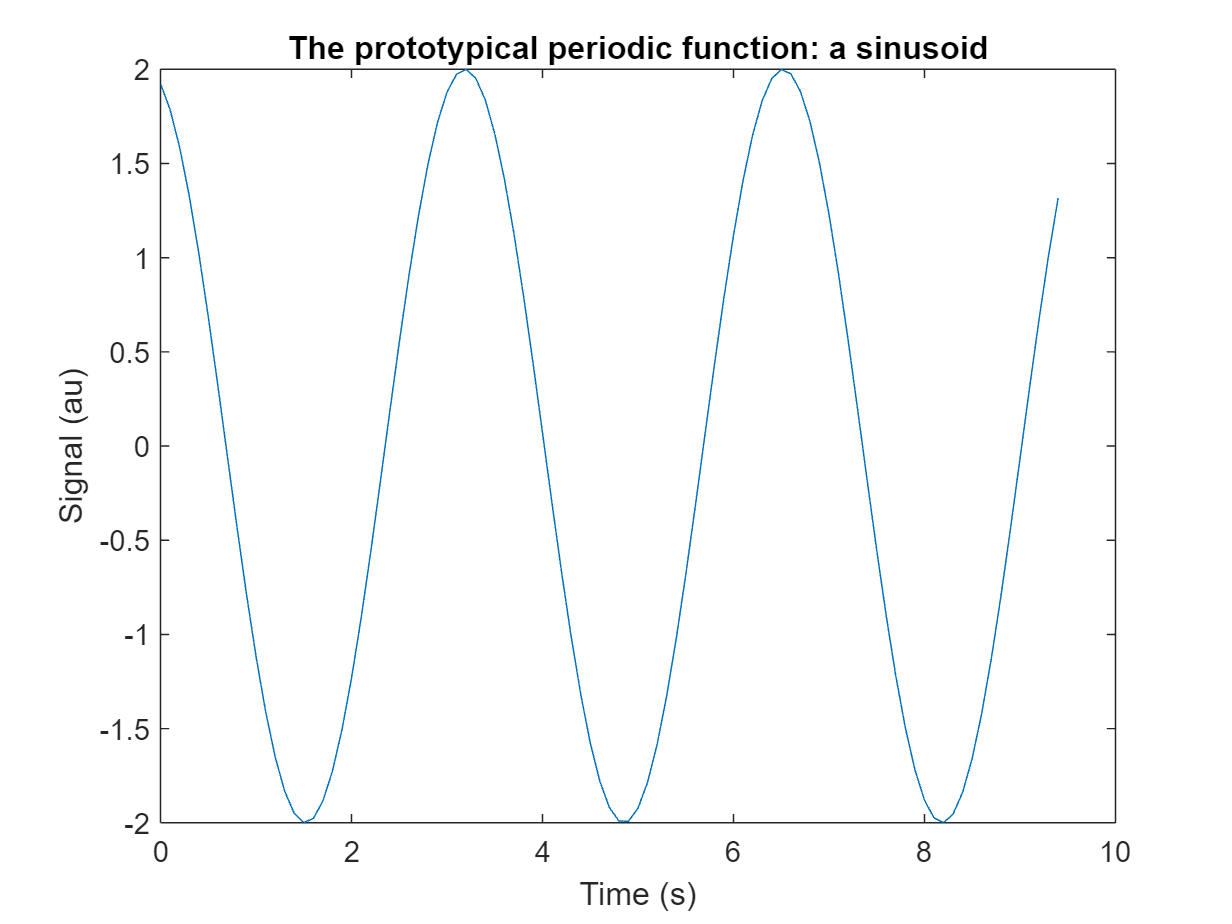

clf
plot(t,y)
xlabel 'Time (s)'
ylabel 'Signal (au)'
title 'The prototypical periodic function: a sinusoid'

No biological signals will be as perfectly periodic as a sine, but the insight that Baron de Fourier had is that *any function* can be written as the sum of many sinusoids. Let's have a look at some sums of sinusoids:

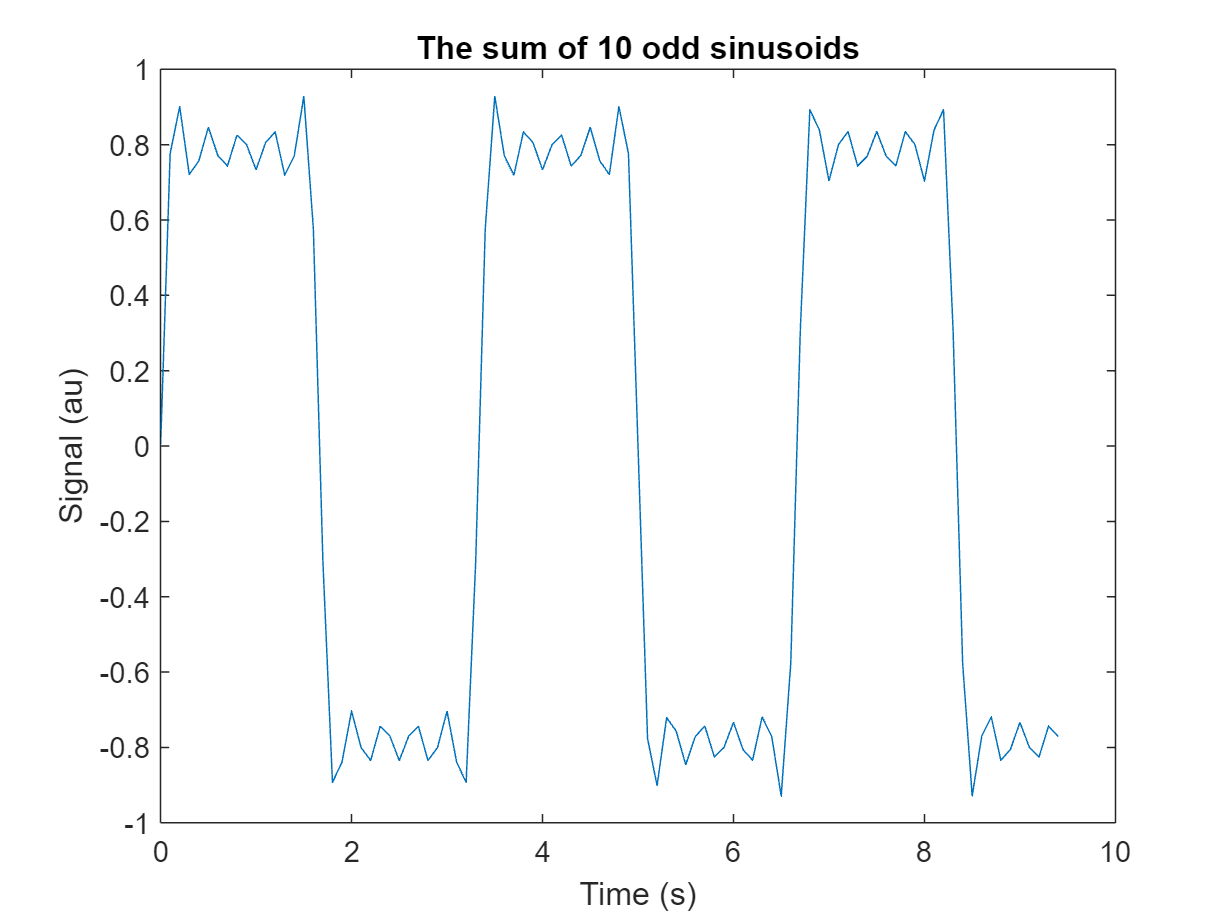

y = zeros(size(t));
clf;
frequency =.3;  % Fundamental (=lowest) frequency of our sum of sinusoids.
N = 10;        % Number of sinusoids to sum
for i=1:2:N
    y = y + 1./i*sin(2*pi*t*frequency*i);
end
plot(t,y);
xlabel 'Time (s)'
ylabel 'Signal (au)'
title(sprintf('The sum of %d odd sinusoids',N))

Apparently this particular sum of the nice and smooth sinusoids results in a signal that is nearly a square wave. By changing the number of sinusoids that are summed to an even higher number (`N` =10000) the approximation of a square wave becomes almost perfect (try it out!)

Here is an example that is only subtly different in the summation, but it results in a very different function `y`:

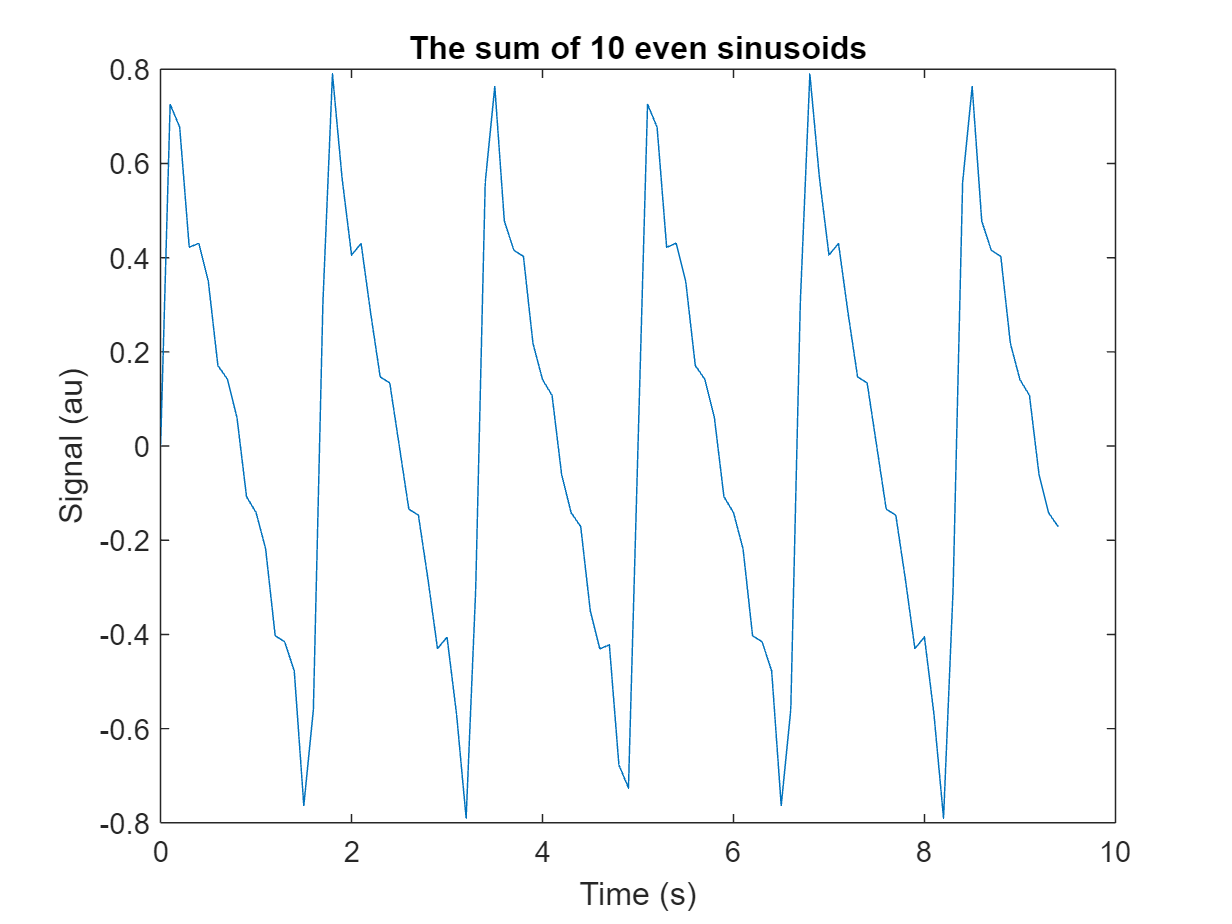

y = zeros(size(t));
for i=2:2:N
    y = y + 1./i*sin(2*pi*t*frequency*i);
end
clf
plot(t,y);
xlabel 'Time (s)'
ylabel 'Signal (au)'
title(sprintf('The sum of %d even sinusoids',N))

These are examples of what are called Fourier series; a series (sum) of sinuosoids. Fourier showed that every function can be written as a Fourier series, even functions that are not periodic.

## The Fast Fourier Transform in Matlab

In data analysis, we don't usually construct a Fourier series by explicit summation. Instead, we extract the best matching Fourier series from the data. The mathematical formulas for doing this are not trivial, but Matlab has built-in functions that do this for us. The main function is called `fft`, for Fast Fourier Transform.

Let's perform a Fourier analysis of a simple square wave:

t                   = linspace(0,6,20);
squareWave          = (t>=2.5);
squareWaveFourierComponents   = fft(squareWave);

The `squareWaveFourierComponents` vector defines all of the sinusoids that the FFT found in the `y` signal. This vector is completely equivalent to the `squareWave` vector. In other words, if you know `squareWave` you can determine `squareWaveFourierComponents` but the reverse is true too: if you know `squareWaveFourierComponents` then you can calculate `squareWave`. Put differently, the `fft` is a *lossless* transformation that can be inverted by another transformation (in Matlab you do this with the `ifft` function.

As discussed above, it takes three numbers to define a sinuosoid (`amplitude`, `frequency`, `phase`), and the `squareWaveFourierComponents` vector contains that information in a relatively complicated way.

The `frequency` is encoded by the order of the elements of the `squareWaveFourierComponents` vector. The first entry in the vector is the sum of the signal (maybe it helps to think of this as a sinusoid with a zero frequency ; it never changes). The second entry in the vector contains the information about the sinusoid that fits exactly once in the `y` vector. This the lowest frequency that could be present in `y` , also called the fundamental frequency. The second entry in the vector contains information on the sinusoid that fits twice in the `y` vector, etc.

The numbers in the `squareWaveFourierComponents` vector encode the amplitude and phase of each sinusoid. Matlab uses one complex number to represent these two quantities. But we can easily extract the amplitude and phase from these complex numbers. These vectors are called the (Fourier) spectrum of the signal.

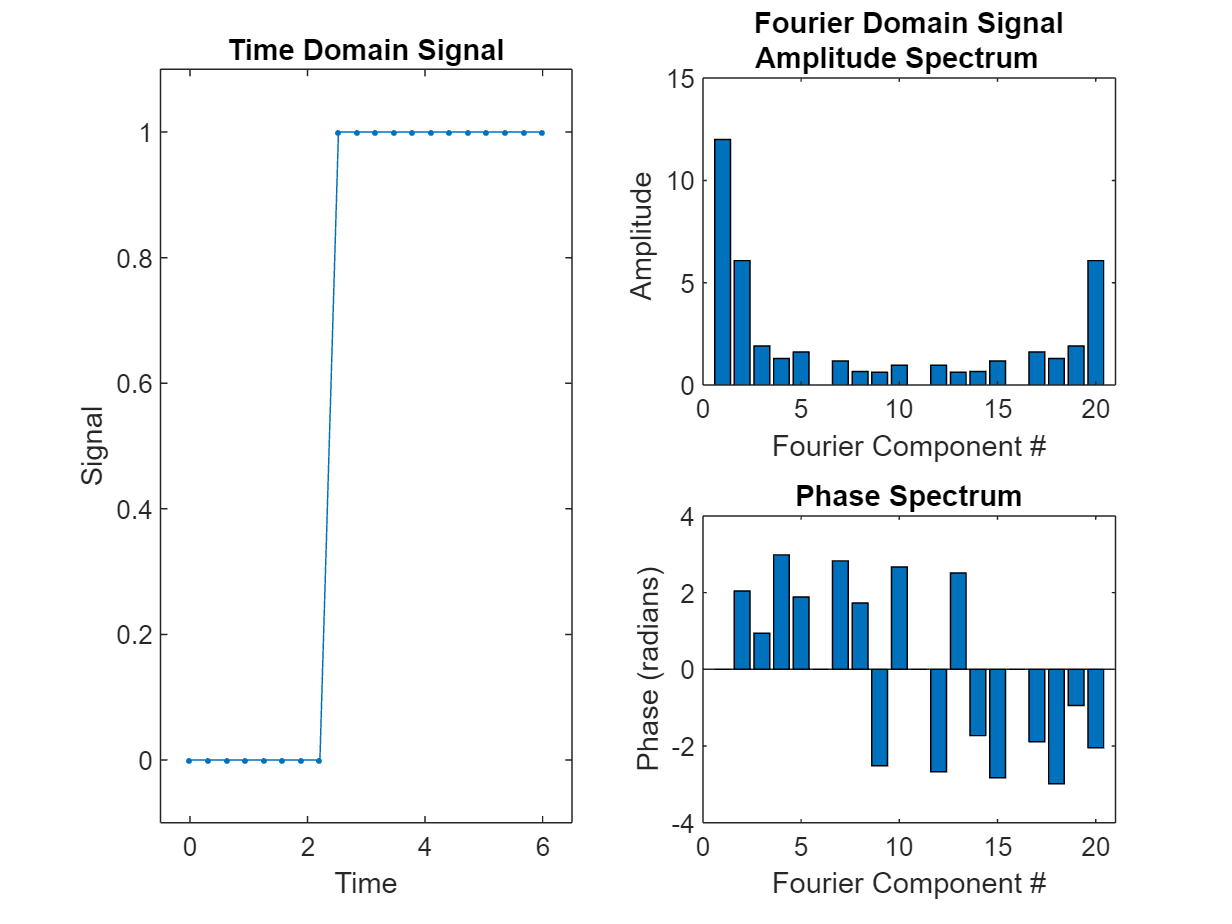

nrComponents        = length(squareWaveFourierComponents);
meanSignal          = squareWaveFourierComponents(1)/nrComponents;
amplitudeSpectrum   = abs(squareWaveFourierComponents);
realPhaseSpectrum   = angle(squareWaveFourierComponents);

clf;
R=2;
C=2;
% Show the original signal
subplot(R,C,[1 3]); % See Code Note 1.
plot(t,squareWave,'.-');
ylabel 'Signal'
xlabel 'Time'
set(gca,'ylim',[-0.1 1.1],'Xlim',[-0.5 6.5])
title 'Time Domain Signal'

% Show the amplitude spectrum
subplot(R,C,2);
bar(amplitudeSpectrum)
ylabel 'Amplitude '
xlabel 'Fourier Component #'
set(gca,'Xlim',[0 nrComponents+1])
title (char('Fourier Domain Signal','Amplitude Spectrum'))

% Show the phase spectrum
subplot(R,C,4);
bar(realPhaseSpectrum)
set(gca,'Xlim',[0 nrComponents+1])
ylabel 'Phase (radians)'
xlabel 'Fourier Component #'
title ('Phase Spectrum')

It is critical to understand that the data on the left (the signal in the time domain) are completely equivalent to the data on the right (the signal in the Fourier domain). No information is lost (or gained) when transforming the data into the Fourier domain. The Fourier domain merely shows you a differen view of the same data. Sometimes it is a useful view, sometimes it is not.

Given that no information is lost in the transformation, it is a little odd that the left graph has 20 data points (the value of the signal at each of the 20 time points that we simulated), while the right has 20 amplitudes, and 20 phases. How can 40 numbers contain the same information as 20 numbers?

The explanation is that some of these numbers are duplicates. For instance, the amplitude of component #2 is the same as the amplitude of component #20. The same is true for the phase spectrum: the phase for #2 is -1 times the phase of #20. Due to this symmmetry, there are really only 20 independent numbers in the Fourier spectrum (10 for amplitude, 10 for phase); the same as the number of unique values in the time domain.

This should lead to two questions: why does Matlab return those "superfluous" numbers? And, what does this mean for using `fft` in practice?

Matlab returns those numbers because you could pass a complex time series to `fft`. A complex numbers is merely a compact way to reprsent two numbers that belong together. (A better term for 'complex number' would have been '2D number') When you do an FFT on a complex time series, the upper half of the FFT spectrum can have diffferent numbers than the lower half. As a neuroscientist you typically don't encounter any complex valued quantities, but engineers deal with them all the time, and that is why Matlab's `fft` function assumes that the input can be a complex time series. 

In practice, when you are doing spectral analysis in Neuroscience, there is no point in showing the mirror-symmetric upper half, so you just extract the lower half and base your analysis and graphs on those. However, if you are going back from the Fourier to the Time domain (using `ifft`; see Assignments) then you have to keep the entire representation of Fourier components. (The reason this is that `ifft` has to work for engineers too. For them the top-half could be different from the lower half. Therefore `ifft` cannot simply assume that the top half is the same (but mirrored ) as the bottom half. If you're playing around with the `ifft` and find that your data contain complex values, then you probably passed `ifft` a vector of Fourier components that was not mirror symmetric. 

Above, I mentioned that each of the entries in the FFT corresponds to the amplitude and phase of one particular sinusoid. We can now define those frequencies. There are two important limiting frequencies; the fundametal and the Nyquist frequency.

The lowest frequency in the Fourier spectrum (the fundamental) fits in the signal exactly once. Lower frequencies of course exists, but your signal cannot contain those because you did not measure long enough. (Think of measuring the periodicity of the sun; if you take measurements every hour and measure for 24 hours then your data provide information on the periodicity on the scale of 24 hours (i.e. the rotation of the earth around its own axis). However, you could not use those measurements to say something about the periodicity of sunlight on the time scale of a year. That frequencye (1 cycles/year = 1/365 =0.0027 cycles/day) is much lower than the fundamental frequency of your measurements (1 cycle/day).

To calculate the fundamental we first calculate some properties of the data acquisition:

nrSamples = length(squareWave);
sampleTime  = 1; % The time between samples in some unit of time (e.g. seconds, days, milliseconds).
samplingRate = nrSamples/(nrSamples*sampleTime); % The number of samples per unit of time.

Note that the units of time are arbitrary. That said, make sure you are consistent in your choice of units. If you define your `sampleTime` in milliseconds then your `samplingRate` will be in cycles/millisecond. In general it is probably best to stick to seconds for measurements of time, then the sampling rate is cycles/second, which corresponds to the Herz unit, which is abbreviated as Hz in the SI system. 

So let's assume that our time vector (`t` above) was in seconds, then the fundamental frequency is in Hz:

fundamentalFrequency = 1./(nrSamples*sampleTime); % Hz .

The highest possible frequency that a discrete (sampled) signal can contain is called the Nyquist frequency. Its frequency is exactly half the rate at which the samples were obtained.

nyquistFrequency     =  samplingRate/2; % Units of Hz

The Nyquist frequency is an important concept in Fourier analysis. Let's go back to the sun example. If you measured the amount of sunlight every day at the same time then your `samplingRate` is 1/day. Those measurements give no useful information about the periodicity of the rotation of the earth becuase the Nyquist frequency corresponding to this `samplingRate` is 0.5 cycles/day, which is below the earth's rotation frequency (1 cycle/day). Your measurements will not have any useful information about that frequency. 

As an aside, please note that if the true signal actually contains periodic signals above the Nyquist frequency then those signals will show up in the lower frequencies. This is called aliasing. In the sun example, if you take a light measurement every 36 hours, then there will be some variation in the signal due to the fact that the earth rotates ( your samples will alternate between high and low light levels due to the earth's rotation). This variation will be in your samples, but because your sampling rate is too low, these data will not allow you to detect the earth's daily cycle. Instead, this variation will contaminate some of your measurements of the slower cycles (such as the annual cycle). To prevent this contamination (aliasing) from happening, sampled signals are usually filtered to remove signals above the Nyquist rate. More on this important concept later. 

The next step is to construct a frequency axis for our Fourier spectrum. By convention, the vector of Fourier components returned by `fft` orders the frequencies in ascending order (up to the Nyquist frequency) and then in descending order (just for the engineers).

In other words: 

- The first component has zero frequency; it is the sum of the signal.

- The second comppnent has one cycle over the whole duratiom

- The third component has two cycles over the whole duration.

- ... etc.

- Until we reach the point halfway between the 2nd and the last entry in the component vector.

- If the number of samples is even, then the highest frequency is the Nyquist frequency. 

- If the number of samples is odd, then the highest frequency is just below the Nyquist frequency 

- Once we're past the nyquist frequency, the frequencies decrease again until we're back at the fundamental. 

We can capture this relatively complex relationship as follows: See Code Note 2.

if rem(nrSamples,2)==0
    % Even number of samples. Nyquist is the highest one
    frequency = [0 1:nrSamples/2 (nrSamples/2-1):-1:1]*samplingRate/nrSamples;  
    [~,highestFrequencyIx] =max(frequency);
else
    % Odd number of samples. Nyquist is not in the set.
    frequency = [0 1:(nrSamples-1)/2 (nrSamples-1)/2:-1:1]*samplingRate/nrSamples;
    [~,highestFrequencyIx] =max(frequency);
end

As long as we are just looking at the spectrum (and don't plan to use `ifft `later), we do not care about those duplicated values on the far-end of the spectrum . We use an index to keep only the values up to the Nyquist limit (or just below for odd `nrSamples`.

keep = 1:highestFrequencyIx;
frequency = frequency(keep);
realAmplitudeSpectrum = amplitudeSpectrum(keep);
realPhaseSpectrum = realPhaseSpectrum(keep);

Now we can create a figure showing the amplitude and phase spectrum with proper frequency axes.

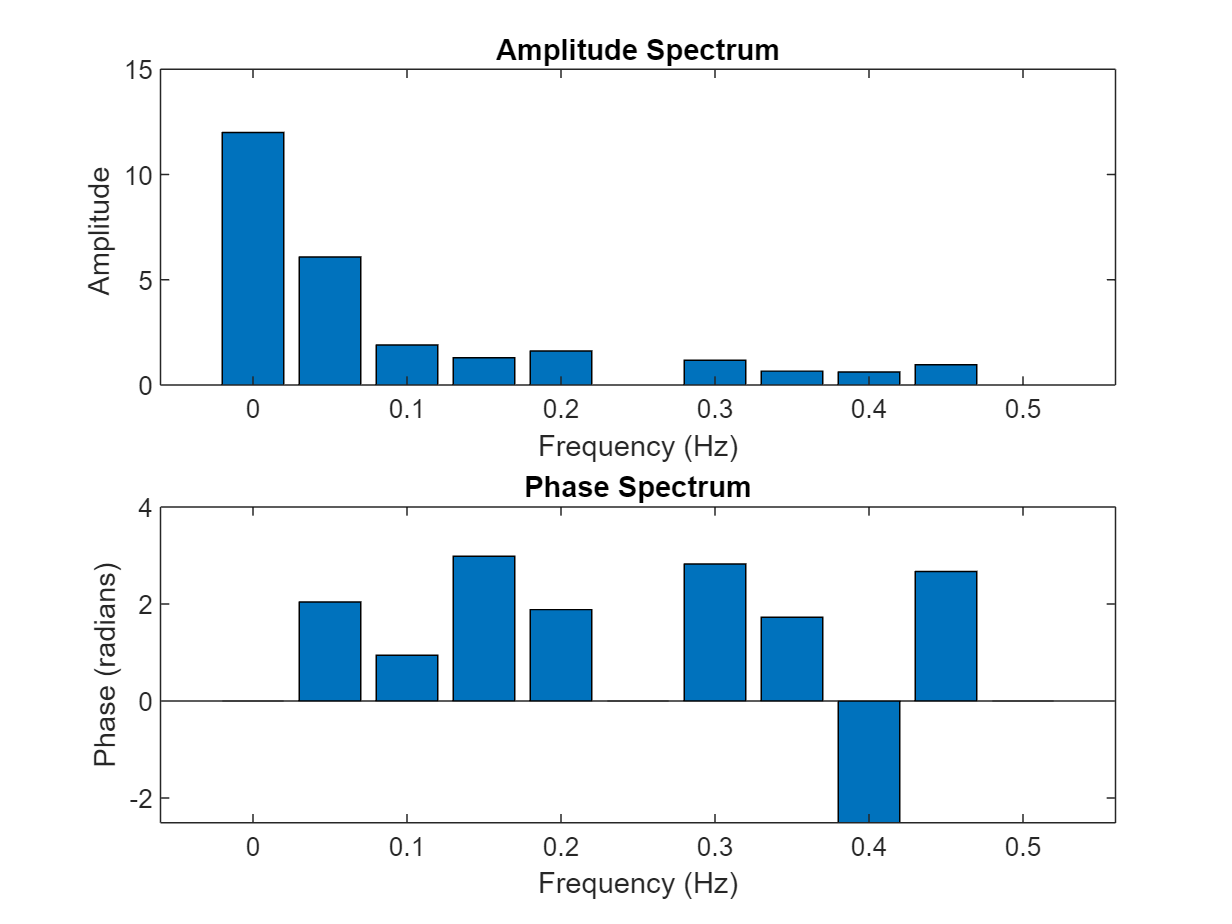

clf;
R=2;C=1;
subplot(R,C,1);
bar(frequency,realAmplitudeSpectrum)
ylabel 'Amplitude '
xlabel 'Frequency (Hz)'
title ('Amplitude Spectrum')

subplot(R,C,2);
bar(frequency,realPhaseSpectrum)
ylabel 'Phase (radians)'
xlabel 'Frequency (Hz)'
title ('Phase Spectrum')

This provides a complete description of the square wave signal in the Fourier domain. The interpretation of the spectrum is as follows. To create the `squareWave` signal , one should add start with a constant value of 11/20 (the amplitude of the 0 frequency corresponds to the sum of the signal. Hence, the mean is sum/nrComponents = 11/20), then add a sinusoidal wave with the fundamental frequency (0.05 Hz), a phase of 2 radians and an amplitude of 6, then add a sinusoidal wave with a frequency of 0.1 Hz, a phase of 0.9 and amplitude of 1.9, then add a sinusoidal wave with a frequency of 0.15 Hz, a phase of 2.9 and amplitude of 1.3,...,etc. until you get to component #10 with frequency 0.45 Hz.

The beauty of Fourier analysis is that this is not an approximation, but this is an exact, and completely equivalent representation of the time domain.

Often the 0 frequency comppnent is relatively uninteresting. When it is large (when the signal has a large mean), it can hide the more interesting structure of the rest of the amplitude spectrum. Therefore it is often left out. For instance, this gives a better view of the amplitude spectrum:

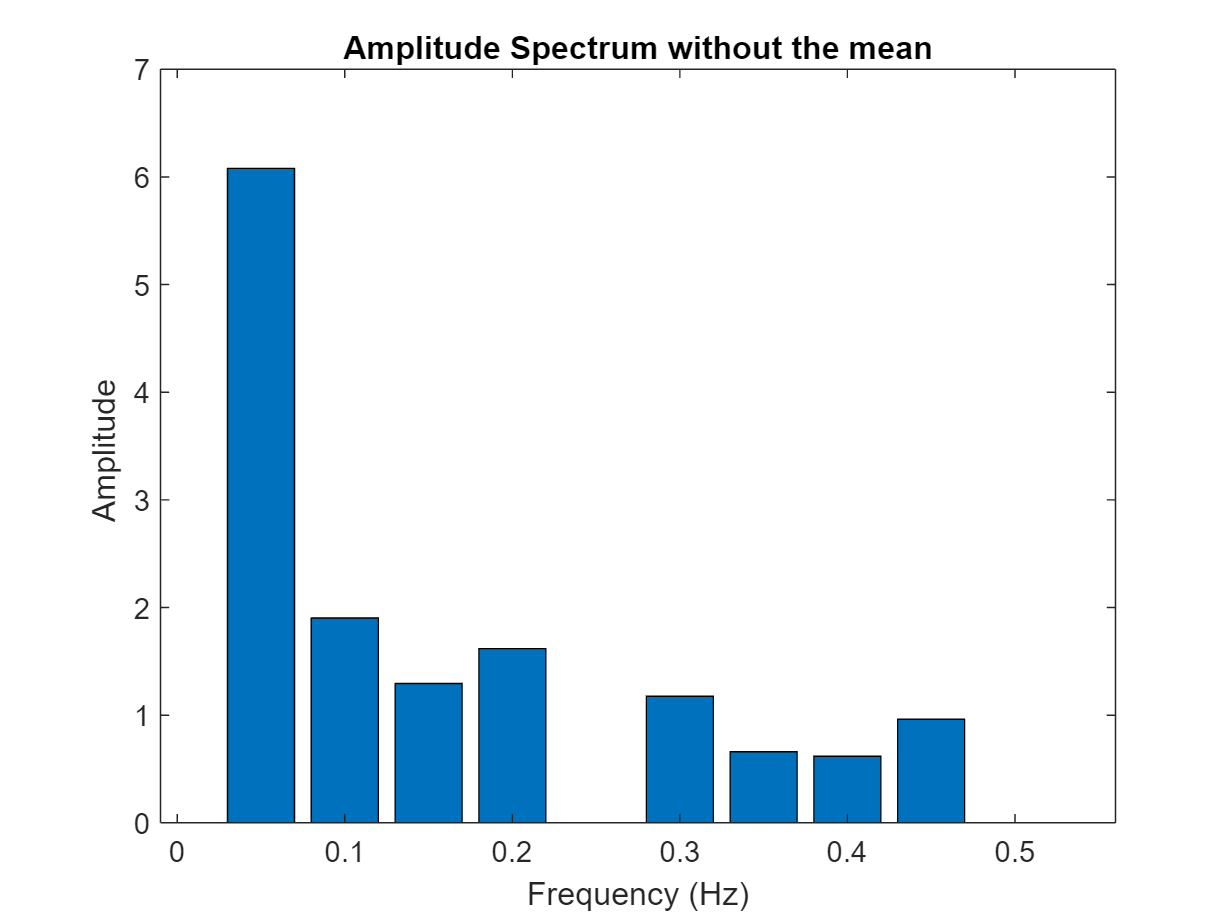

clf;
bar(frequency(2:end),realAmplitudeSpectrum(2:end))
ylabel 'Amplitude '
xlabel 'Frequency (Hz)'
title ('Amplitude Spectrum without the mean')

This immediately shows that the signal (`squareWave` ) is dominated by the fundamental frequency of 0.05 Hz. That is exactly the kind of insight that Fourier analysis is used for; extracting dominant modes of periodic signal changes.

Note that instead of the amplitude spectrum people often use the **power spectrum**, this is simply the square of the amplitude spectrum. Qualitatively, however, there is no difference.

## Applying Fourier Analysis to Example Data

Now that we know how to do Fourier analysis, we can apply it to the data in the example sets. These examples simply follow the steps we went through above with the abstract square wave signal.

### Periodic BOLD Signal Analysis

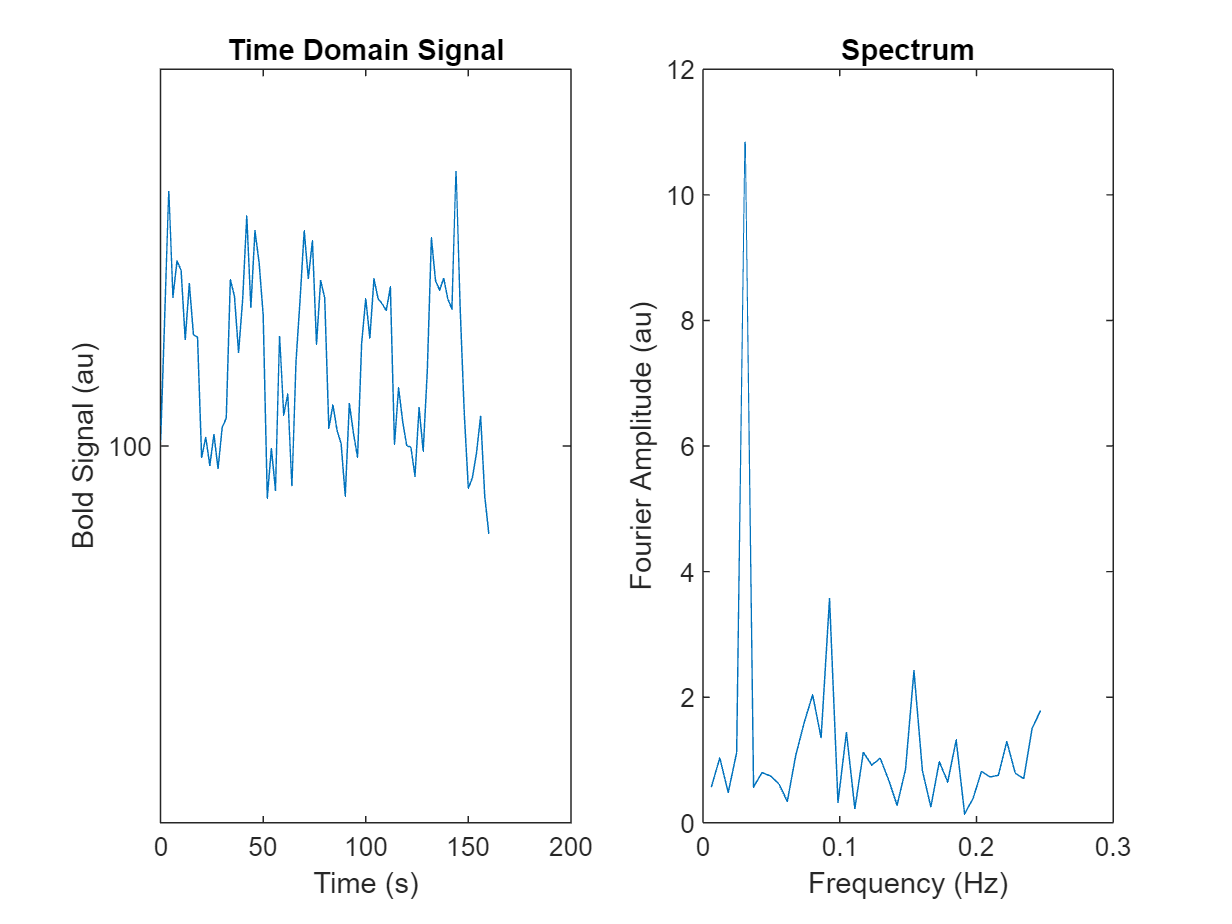

boldFourierComponents = fft(bold); % Get the Fourier components. 
meanBold = boldFourierComponents(1);
nrSamples =length(bold);
sampleTime = TR; % Time between samples is the TR.
samplingRate = 1./sampleTime; 
if rem(nrSamples,2)==0
    % Even number of samples. Nyquist is the highest one
    frequency = [0 1:nrSamples/2 (nrSamples/2-1):-1:1]*samplingRate/nrSamples;  
    [~,highestFrequencyIx] =max(frequency);
else
    % Odd number of samples. Nyquist is not in the set.
    frequency = [0 1:(nrSamples-1)/2 (nrSamples-1)/2:-1:1]*samplingRate/nrSamples;
    [~,highestFrequencyIx] =max(frequency);
end

keep = 2:highestFrequencyIx;
frequency = frequency(keep);
realAmplitudeSpectrum = abs(boldFourierComponents(keep));

clf;
R=1;C=2;
subplot(R,C,1);
plot(boldTime,bold);
xlabel 'Time (s)'
ylabel('Bold Signal (au)');
set(gca,'YLim',[99 101],'YTick',100)
title 'Time Domain Signal'

subplot(R,C,2);
plot(frequency,realAmplitudeSpectrum);
xlabel 'Frequency (Hz)'
ylabel('Fourier Amplitude (au)');
title 'Spectrum'

This spectrum shows that the signal is dominated by the component near 0.03 Hz. Let's determine this peak programmatically:

[maxAmplitude,maxIx] = max(realAmplitudeSpectrum);
dominantFrequency = frequency(maxIx)

dominantFrequency = 0.0309

dominantPeriod = 1./dominantFrequency

dominantPeriod = 32.4000

This peak corresponds to the period of the paradigm: 16 s Faces, followed by 16 s of Houses, hence the period is 32 s and the BOLD signal appears to follow that sitmulation frequency quite nicely. That is evidence that this voxel responds much more to one of the categories than the other and is a powerful way to demonstrate selectivity in block-design BOLD imaging data.

### Periodic spiking responses

Next, we'll determine the Fourier (amplitude) spectrum of the V1 data:

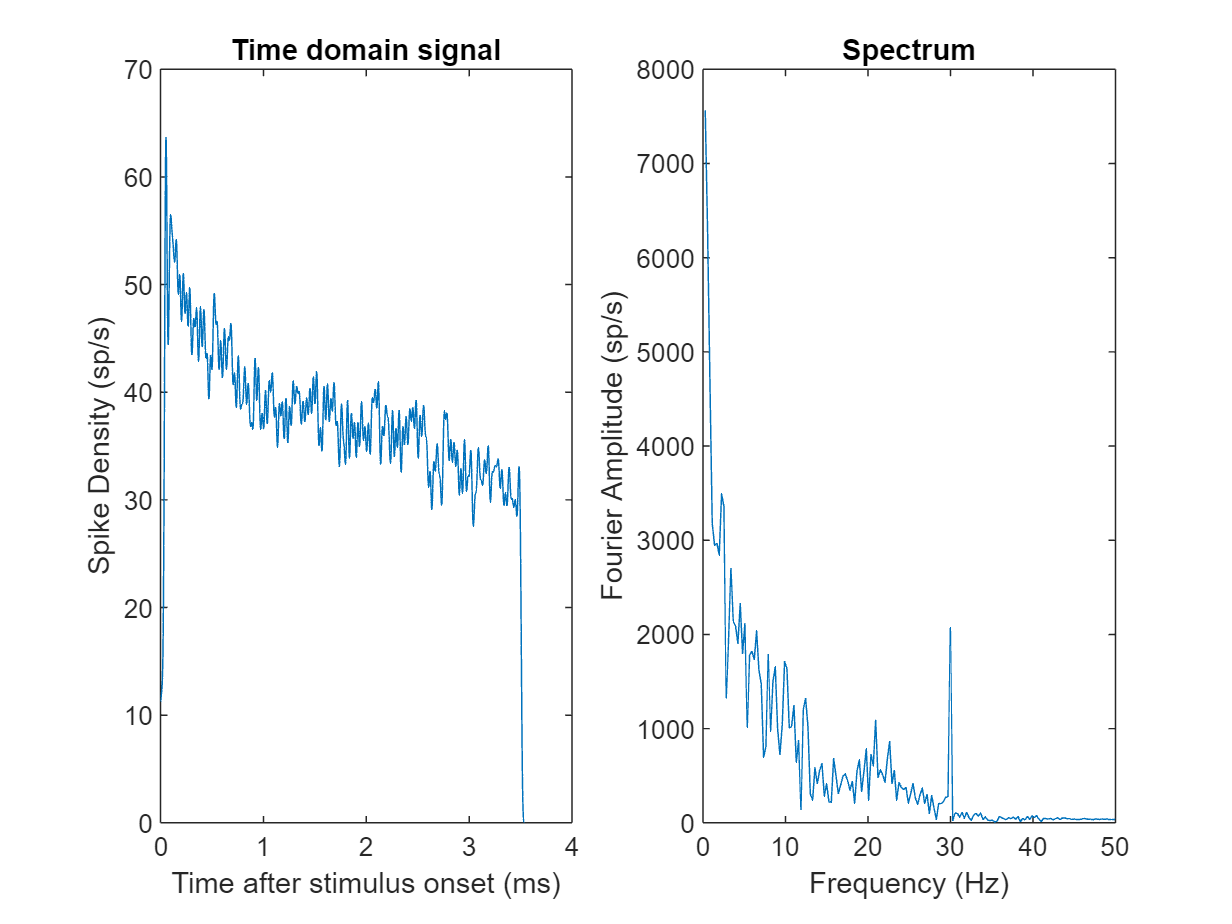

v1FourierComponents = fft(v1Response);
meanV1 = v1FourierComponents(1);
nrSamples =length(v1Response);
sampleTime = 0.001; % Time between samples: 1 ms

samplingRate = 1./sampleTime; 
if rem(nrSamples,2)==0
    % Even number of samples. Nyquist is the highest one
    frequency = [0 1:nrSamples/2 (nrSamples/2-1):-1:1]*samplingRate/nrSamples;  
    [~,highestFrequencyIx] =max(frequency);
else
    % Odd number of samples. Nyquist is not in the set.
    frequency = [0 1:(nrSamples-1)/2 (nrSamples-1)/2:-1:1]*samplingRate/nrSamples;
    [~,highestFrequencyIx] =max(frequency);
end

keep = 2:highestFrequencyIx; % Remove sum (ix=1) and the duplicate values above nyquistIx.
frequency = frequency(keep);
realAmplitudeSpectrum = abs(v1FourierComponents(keep));

clf;
R=1;C=2;
subplot(R,C,1)
plot(v1Time,v1Response);
xlabel 'Time after stimulus onset (ms)'
ylabel 'Spike Density (sp/s)'
title 'Time domain signal'

subplot(R,C,2)
plot(frequency,realAmplitudeSpectrum);
xlabel 'Frequency (Hz)'
ylabel 'Fourier Amplitude (sp/s)'
title 'Spectrum'
xlim([0 50]) % There isn't much of interest above 50 Hz.

This amplitude spectrum shows a number of interesting features. First, there is a conspicuous peak in the spectrum at 30 Hz. This is the frequency with which the orientation of the bars on the screen changed (one stimulus every 33 ms). So, this shows that the response of this neuron follows the presentation of the visual stimuli. A cell in the auditory cortex should not show such a peak.

However, there are also other peaks. Some of these other peaks are relatively easy to understand. For instance, from the time domain plot you can see that this cell shows spike frequency adaptation: it starts out responding strongly at the beginning of the trial, but the firing rate drops over time. This is typical for many sensory neurons. As you can see from the time domain plot, this adaptation process plays out on a time scale of several seconds (and possibly longer) in this neuron. As a consequence, the Fourier spectrum has significant power in the lower frequencies (<1Hz). This is important: even though the adaptation process itself is not periodic, the spectrum is dominated by the low-frequency components. 

## Code Notes

- I often use such R,C variables when setting up a multipanel plot as it allows me to add plots more easily later on. For instance if I decide that I need another row of plots, I simply increase R in one place in the code, and it automtically works for all the `subplot` commands. This makes the code more reusable and easier to maintain.

- The calculation to determine the frequencies in an FFT is confusing, and you may have to use it many time (this script already copies the same code three time...). This is a clear candidate for a function that you should add to your own toolbox. In this function you should check that the signal input does not contain complex numbers, and you'll do yourself a favor if you return both the (complex) Fourier spectrum and the corresponding frequencies. 